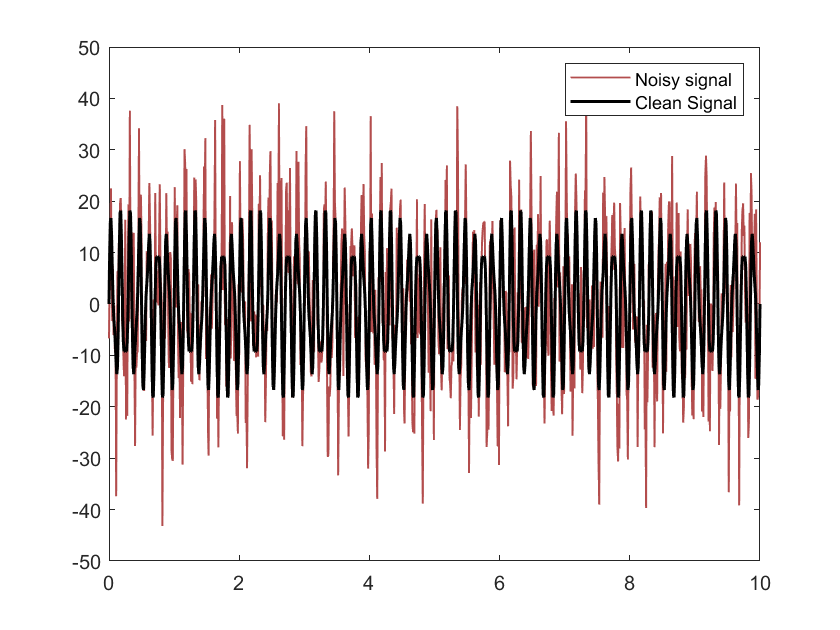

clear; close; clc;
dt = .01; % time step of signal
L = 10;
t = 0:dt:L;
% signal: sum of two sines at 13 Hz and 7 Hz
xclean = (14*sin (7*2*pi*t)+5*sin(13*2*pi*t));
% add noise to signal
x = xclean + 10*randn(size(xclean));
ylim ([-40 40])
plot(t,x,'Color',[.7 .3 .3],'LineWidth',.9), hold on
plot(t,xclean ,'k','LineWidth',1.5)
legend('Noisy signal','Clean Signal')


figure
xhat = fft(x);
N = length(t); % number of samples
xpower = abs(xhat (1:N/2+1))*2/N;

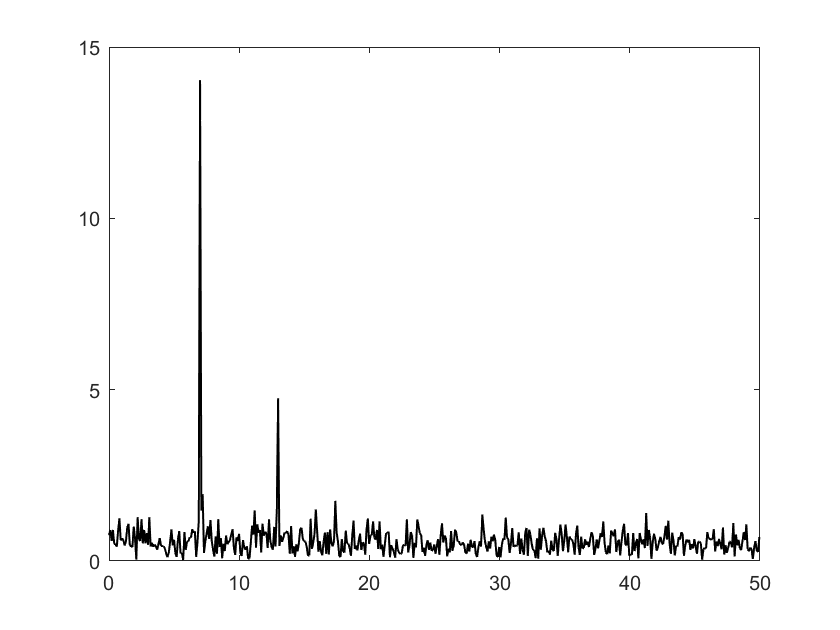

Fs = 1/dt; % sampling frequency
freqs = Fs*(0:(N/2))/N;
plot(freqs ,xpower ,'k','LineWidth',1.2)
hold on




s = 500; % number of times to shift -stack signal
for k = 1:s
X(k,:) = x(k:end -s+k);
end
[U,S,V] = svd(X(:,1:end -1),'econ');
% keep 50 modes and compute DMD spectrum Lambda
r = 50;
Atilde = U(:,1:r)'*X(:,2:end)*V(:,1:r)*inv(S(1:r,1:r));
[W,Lambda] = eig(Atilde);
% convert eigenvalues to continuous time
DMDfreqs = log(diag(Lambda))/dt/2/pi;
Phi = X(:,2:end)*V(:,1:r)*inv(S(1:r,1:r))*W;
% mode amplitude (based on first snapshot)
b = Phi\X(:,1);
% need to scale power by 2/sqrt(s)
DMDpower = abs(b)*2/sqrt (s);


scatter(abs(imag(DMDfreqs)),DMDpower ,'r')
legend('FFT','DMD')
hold on

% % approximation using POD subspace
% alpha1 = S(1:r,1:r)*V(1,1:r)';
% %bPOD = (Atilde*W)\alpha1;
% bPOD = (W*Lambda)\alpha1; % equivalent
% foo = norm(b-bPOD ,2)
% 
% scatter(abs(imag(bPOD)),abs(bPOD))
